clear all;
tbUseProject('ISETTreeShrew');

Locating project "ISETTreeShrew" within "C:\Users\eemeyer\Documents\MATLAB\projects".
  Found at "C:\Users\eemeyer\Documents\MATLAB\projects\ISETTreeShrew".
Local copy of ToolboxToolbox is up to date.
Updating "ToolboxRegistry".
Already up to date.
Obtaining "ISETTreeShrew".
fatal: destination path 'C:\Users\eemeyer\Documents\MATLAB\projects\ISETTreeShrew' already exists and is not an empty directory.
Updating "isetbio".
Already up to date.
Updating "UnitTestToolbox".
Already up to date.
Updating "RemoteDataToolbox".
Already up to date.
Found "jsonlab_v1.2" and skipping update.
Found "Palamedes_1.8.2" and skipping update.
Resetting path to factory state.
Adding "ToolboxToolbox" to path at "C:\Users\eemeyer\Documents\MATLAB\ToolboxToolbox".
Adding "ISETTreeShrew" to path at "toolbox".
Adding "ISETTreeShrew" to path at "tutorials".
Adding "ISETTreeShrew" to path at "compute".
Adding "ISETTreeShrew" to path at "validations".
Adding "isetbio" to path at "C:\Users\eemeyer\Documents\MATLAB\t


% this code contains the original functions from iset bio used to make
% figures
% [theWVFOI,wvfP2] = oiTreeShrewCreate('opticsType', 'wvf', ...
%     'name', 'wvf-based optics');
% 
% psfRangeArcMin = 50;
% visualizedSpatialSfrequencyCPD = 10.0;
% targetWavelength = 500;
% visualizeOptics(theWVFOI, targetWavelength, ...
%     psfRangeArcMin, ...
%     visualizedSpatialSfrequencyCPD, ...
%     'extraOTFData',  mtfTreeShrewFromPaper('SaidakEtAl_2019'));

## Unpacked oiTreeShrewCreate

% SPECIFY WAVELENGTH(S) AND TREE SHREW(S) HERE:
targetWavelength = 450:50:900; %450:50:900
TSindex = 1:11; %1:11

% from opticsTreeShrewDefaultParams
opticstype = 'wvf';
focalLengthMM = 4.35;
pupilDiameterMM = 3.0;

% from opticsTreeShrewCreate
opticsName = 'wvf-based optics';
wavelengthSupport = 450:10:900;

focalLengthMeters = focalLengthMM / 1000;
posteriorNodalDistanceMM = focalLengthMM;
micronsPerDegree = posteriorNodalDistanceMM * 1000 * tand(1);
optics.micronsPerDegree = micronsPerDegree;

optics.type = 'optics';
optics = opticsSet(optics, 'model', 'shiftInvariant');

measuredDiameterMM_TreeShrew = 4.0;

% 840 nm light used in measurements of Sajdak et al 2019 (section 2.2)
measuredWavelength = 550;
spatialsamples = 1001;
psfRangeArcMin = 50;
visualizedSpatialSfrequencyCPD = 10.0;

% read in Zernicke coefficients as matrix
zCoeffs = cell2mat(readcell('Tree_Shrew_Aberrations_Remeasured_Oct2018.xlsx','Sheet','Aberration Summaries','Range','B7:L71'));
zCoeff4 = cell2mat(readcell('Tree_Shrew_Aberrations_Remeasured_Oct2018.xlsx','Sheet','Aberration Summaries','Range','B95:L95'));

mtfSlice = zeros(length(targetWavelength),length(TSindex),spatialsamples);
for ts = 1:length(TSindex)

% Defocusm with coefficient #4, (#5 in Matlab' indexing) is by far the dominant Zcoeffs in measurents of Sajdak et al 2019
% So we are setting all the other coeffs to 0.
% The data here are from Figure 2 of Sajdak et al 2019

zCoeffs_TreeShrew = zeros(1,size(zCoeffs,1)+1);
zCoeffs_TreeShrew(2:end) = zCoeffs(:,TSindex(ts));
zCoeffs_TreeShrew(5) = zCoeff4(TSindex(ts));

% zCoeffs_TreeShrew = randn(1,20)*0.0;
% %zCoeffs_TreeShrew(4) = -0.15;
% zCoeffs_TreeShrew(5) = -2.75;

wvfP = wvfCreate(...
    'spatialsamples', spatialsamples, ...
    'measured wl', measuredWavelength, ... 
    'calc wavelengths', wavelengthSupport, ...
    'zcoeffs', zCoeffs_TreeShrew, ...
    'name', sprintf('treeshrew-%d', pupilDiameterMM), ...
    'umPerDegree', micronsPerDegree,...
    'customLCA', @treeShrewLCA);

wvfP = wvfSet(wvfP, 'measured pupil size', measuredDiameterMM_TreeShrew);
wvfP = wvfSet(wvfP, 'calc pupil size', pupilDiameterMM);
wvfP = wvfComputePSF(wvfP);
    
optics = oiGet(wvf2oi(wvfP), 'optics');

% Set the optics name
optics.name = opticsName;

% Set the focal length
optics = opticsSet(optics, 'focalLength', focalLengthMeters);

% Set the f-Number.
optics = opticsSet(optics, 'fnumber', focalLengthMeters*1000/pupilDiameterMM);

% get pupil diameter to check with opticsGet
% cos-4th off-axis attenuation
optics = opticsSet(optics, 'offAxisMethod', 'cos4th');

% Pixel vignetting is off
optics.vignetting =  0;

% from oiTreeShrewCreate
oi.type = 'opticalimage';
oi = oiSet(oi, 'optics', optics);
oi = oiSet(oi, 'name', 'treeshrew');

oi = oiSet(oi, 'bit depth', 32);
oi = oiSet(oi, 'diffuser method', 'skip');
oi = oiSet(oi, 'consistency', 1);

% from lensTreeShrewCreate
% TreeShrew lens absorption.
lensAbsorbanceFile = 'treeshrewLensAbsorbance.mat';
targetWavelenth = wavelengthSupport;

% TreeShrew lens absorption. Start with the human lens.
theLens = Lens();

% Load TreeShrew lens unit-density
load(lensAbsorbanceFile, 'wavelength', 'data');

if (isempty(targetWavelenth))
    targetWavelenth = wavelength;
    unitDensity = data;
else
    % Interpolate to optics wavelength support
    unitDensity = interp1(wavelength,data,targetWavelenth, 'pchip');
end

% Update the lens
set(theLens,'wave', targetWavelenth);
set(theLens,'unitDensity',unitDensity);

% from oiTreeShrewCreate
% Update the oi.lens
oi = oiSet(oi, 'lens', theLens);

% Set the same lens in the optics structure too
oi.optics.lens = theLens;


## Unpacked visualizeOptics

for ww = 1:length(targetWavelength)
optics = oiGet(oi, 'optics');

wavelengthSupport = opticsGet(optics, 'wave');
[~,idx] = min(abs(wavelengthSupport-targetWavelength(ww)));
targetWave = wavelengthSupport(idx);

% Get PSF slice at target wavelength
wavePSF = opticsGet(optics,'psf data',targetWave);
% psfC = psfCircularlyAverage(wavePSF);

% Extract support in arcmin
psfSupportMicrons = opticsGet(optics,'psf support','um');
if (isfield(optics, 'micronsPerDegree'))
    micronsPerDegree = optics.micronsPerDegree;
else
    focalLengthMeters = opticsGet(optics, 'focalLength');
    focalLengthMicrons = focalLengthMeters * 1e6;
    micronsPerDegree = focalLengthMicrons * tand(1);
end

xGridMinutes = 60*psfSupportMicrons{1}/micronsPerDegree;
yGridMinutes = 60*psfSupportMicrons{2}/micronsPerDegree;
xSupportMinutes = xGridMinutes(1,:);
ySupportMinutes = yGridMinutes(:,1);
xSfCyclesDeg = opticsGet(optics, 'otf fx', 'cyclesperdeg');
ySfCyclesDeg = opticsGet(optics, 'otf fy', 'cyclesperdeg');

[xSfGridCyclesDeg,ySfGridCyclesDeg,otfraw] = PsfToOtf(xGridMinutes,yGridMinutes,wavePSF);
otf = psfCircularlyAverage(abs(otfraw));

waveMTF = abs(otf);
[~,idx] = min(abs(ySfCyclesDeg));
mtfSlice(ww,ts,:) = waveMTF(idx,:);
end

end


## Plot Avg MTF for each WL

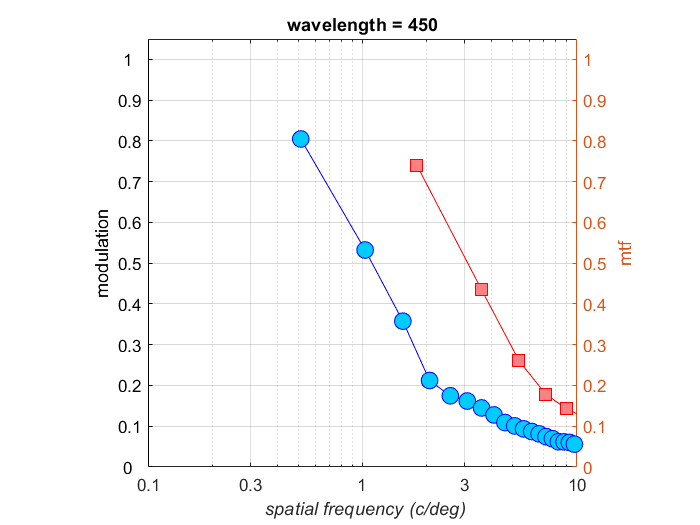

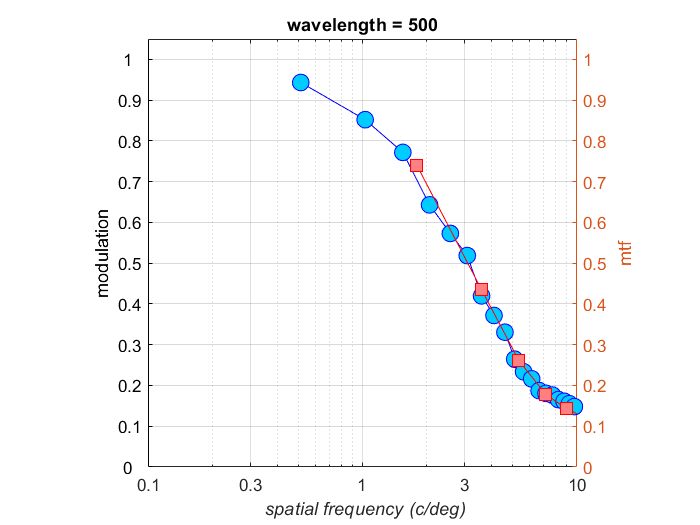

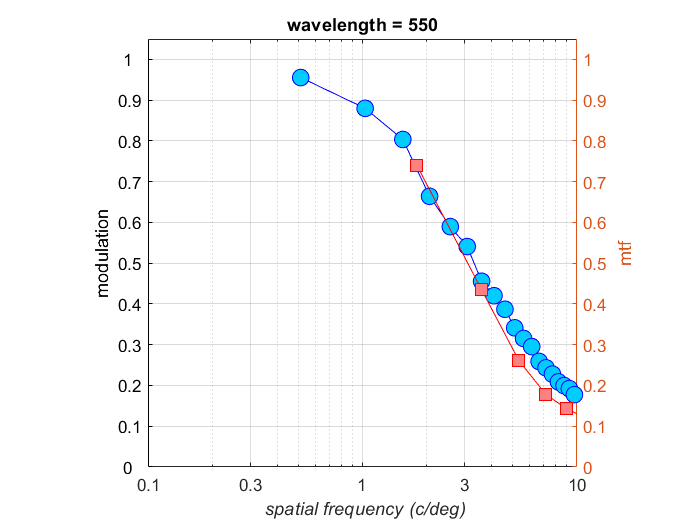

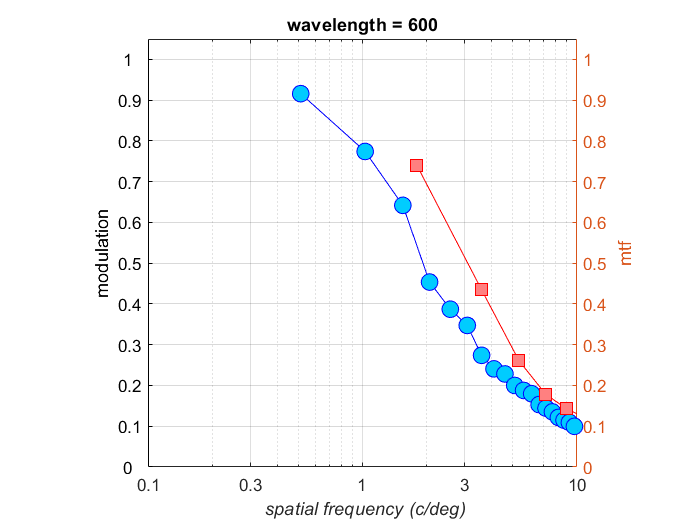

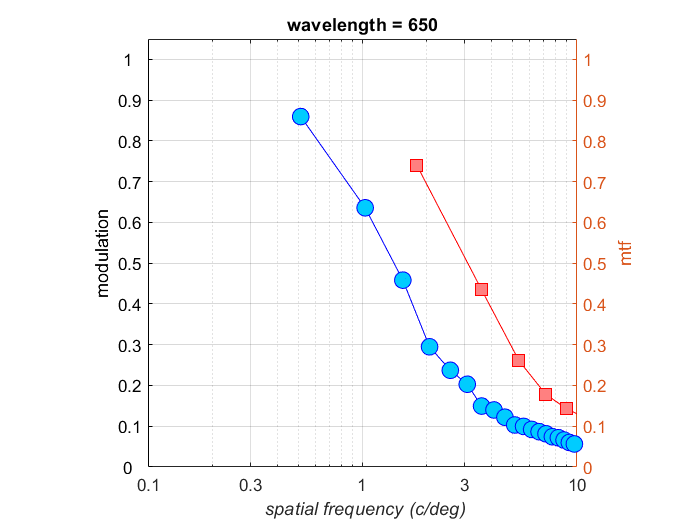

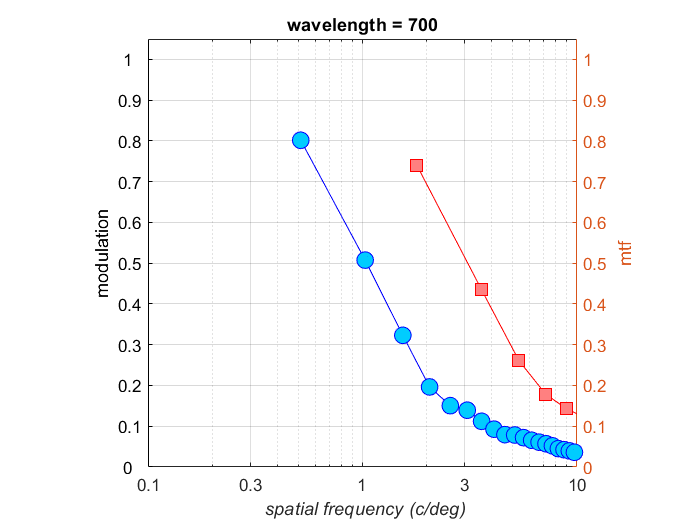

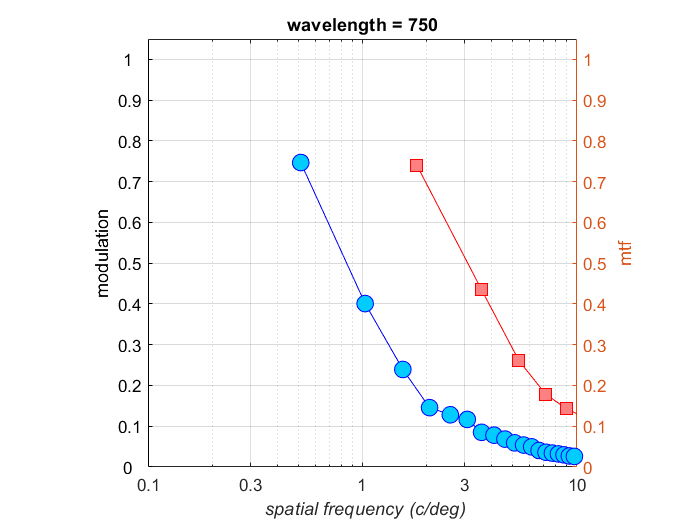

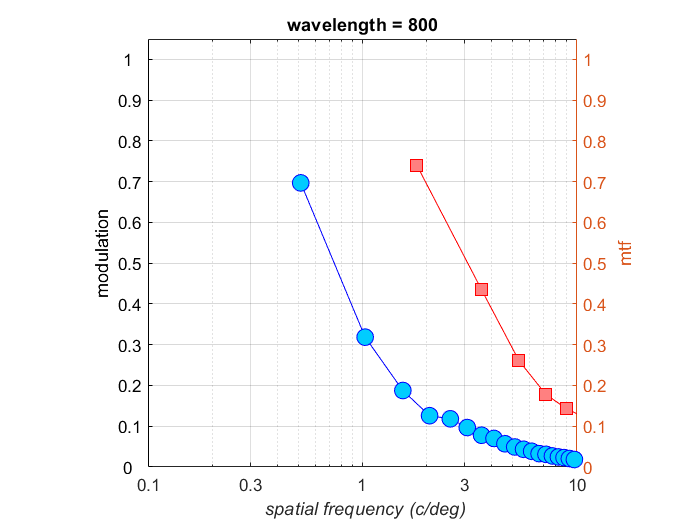

MTFrows = 'B':'L';
for ww = 1:length(targetWavelength)
    
figure; hold on;
plot(xSfCyclesDeg, squeeze(mean(mtfSlice(ww,:,:),2)), 'bo-', 'MarkerFaceColor', [0 0.8 1.0], 'MarkerSize', 10);
set(gca, 'YTickLabel', 0:0.1:1, 'YTick', 0:0.1:1.0, 'YLim', [0 1.05]);
ylabel('modulation');

sfTicks = [0.01 0.03 0.1 0.3 1 3 10 30 100];
set(gca, 'XLim', [visualizedSpatialSfrequencyCPD/100 visualizedSpatialSfrequencyCPD], 'XScale', 'log');
set(gca, 'XTick', sfTicks);
axis('square')
grid('on'); box('on');
xlabel('\it spatial frequency (c/deg)', 'FontWeight', 'normal');
title(['wavelength = ',num2str(targetWavelength(ww))])

% digitized graph
% extraData = mtfTreeShrewFromPaper('SaidakEtAl_2019');
% extraData = extraData{1};
% extraData.csf = extraData.csf/max(extraData.csf);

% max Strehl
extraData = struct;
extraData.sf = cell2mat(readcell('Tree_Shrew_Aberrations_Remeasured_Oct2018.xlsx','Sheet','MTFs at max Strehl w Astig','Range','A5:A15'));
rowstart = [MTFrows(TSindex(1)),'5'];
rowend = [MTFrows(TSindex(end)),'15'];
extraData.csf = cell2mat(readcell('Tree_Shrew_Aberrations_Remeasured_Oct2018.xlsx','Sheet','MTFs at max Strehl w Astig','Range',[rowstart,':',rowend]));
extraData.legend = 'Saidak et al (2019)';
extraData.ylabel = 'mtf';

% max contrast
% extraData = struct;
% extraData.sf = cell2mat(readcell('Tree_Shrew_Aberrations_Remeasured_Oct2018.xlsx','Sheet','MTFs at max Contrast w Astig','Range','A5:A15'));
% rowstart = [MTFrows(TSindex(1)),'5'];
% rowend = [MTFrows(TSindex(end)),'15'];
% extraData.csf = cell2mat(readcell('Tree_Shrew_Aberrations_Remeasured_Oct2018.xlsx','Sheet','MTFs at max Contrast w Astig','Range',[rowstart,':',rowend]));
% extraData.legend = 'Saidak et al (2019)';
% extraData.ylabel = 'mtf';

yyaxis right
hold on
legends = {'PSF'};
extraDataColors = [1 0 0];
maxY = 0;

plot(extraData.sf, mean(extraData.csf,2), ...
    'rs-', 'MarkerSize', 10, ...
    'MarkerEdgeColor', squeeze(extraDataColors),  ...
    'MarkerFaceColor', squeeze(extraDataColors)*0.5+[0.5 0.5 0.5]);
legends{numel(legends)+1} = extraData.legend;
hold off
set(gca,'YLim', [0 1.05]);
ylabel(extraData.ylabel);

end

function lcaDiopters = treeShrewLCA(wl1NM, wl2NM)
    % We dont have a model LCA for tree shrew yet.
    % Here we model is as the human LCA x 5
    % This creates an LCA difference between 840nm and 550nm of -4.5D
    % as per Sadjak et al (2019), "Noninvasive imaging of the tree shrew eye:
    % Wavefront analysis and retinal imaging with correlative histology"
    
    constant = 1.8859 - (0.63346 ./ (0.001 .* wl1NM - 0.2141));
    lcaDiopters = 1.8859 - constant - (0.63346 ./ (0.001 * wl2NM - 0.2141));
    lcaDiopters = 5.15 * lcaDiopters;
end